%Generating the dataset's summary
summmary(data)

%Splitting the dataset
n = height(data)

n = 569

part = cvpartition(n, 'HoldOut' , 0.3)

part = Hold-out cross validation partition
   NumObservations: 569
       NumTestSets: 1
         TrainSize: 399
          TestSize: 170

idxTrain = training(part)

idxTrain = 569×1 logical array
   0
   1
   1
   1
   0
   0
   0
   1
   1
   1


tblTrain = data(idxTrain, :)

tblTrain = 399×33 table
        id        diagnosis    radius_mean    texture_mean    perimeter_mean    area_mean    smoothness_mean    compactness_mean    concavity_mean    concavePoints_mean    symmetry_mean    fractal_dimension_mean    radius_se    texture_se    perimeter_se    area_se    smoothness_se    compactness_se    concavity_se    concavePoints_se    symmetry_se    fractal_dimension_se    radius_worst    texture_worst    perimeter_worst    area_worst    smoothness_worst    compactness_worst    concav

idxTest = test(part)

idxTest = 569×1 logical array
   1
   0
   0
   0
   1
   1
   1
   0
   0
   0


tblTest = data(idxTest, :)

tblTest = 170×33 table
        id        diagnosis    radius_mean    texture_mean    perimeter_mean    area_mean    smoothness_mean    compactness_mean    concavity_mean    concavePoints_mean    symmetry_mean    fractal_dimension_mean    radius_se    texture_se    perimeter_se    area_se    smoothness_se    compactness_se    concavity_se    concavePoints_se    symmetry_se    fractal_dimension_se    radius_worst    texture_worst    perimeter_worst    area_worst    smoothness_worst    compactness_worst    concavi


%Quality Report for continuous features
a = vartype('numeric')

a = 	table vartype subscript:

		Select table variables matching the type 'numeric'

	See Access Data in a Table.


dataN = data(1:569, a)

dataN = 569×31 table
        id        radius_mean    texture_mean    perimeter_mean    area_mean    smoothness_mean    compactness_mean    concavity_mean    concavePoints_mean    symmetry_mean    fractal_dimension_mean    radius_se    texture_se    perimeter_se    area_se    smoothness_se    compactness_se    concavity_se    concavePoints_se    symmetry_se    fractal_dimension_se    radius_worst    texture_worst    perimeter_worst    area_worst    smoothness_worst    compactness_worst    concavity_worst    con


columnName = cell(width(dataN),1);
Count = zeros(width(dataN),1);
Missing = zeros(width(dataN),1);
Card = zeros(width(dataN),1);
Min = zeros(width(dataN),1);
FirstQuartile = zeros(width(dataN),1);
Mean = zeros(width(dataN),1);
Median = zeros(width(dataN),1);
ThirdQuartile = zeros(width(dataN),1);
Max = zeros(width(dataN),1);
StdDev = zeros(width(dataN),1);


for col = 1: width (dataN)
	columnName(col,1) = dataN.Properties.VariableNames(col);
	Count(col,1) = height(data.(col));
	Missing(col,1) = sum(ismissing(dataN.(col))) / height(dataN) * 100;
	Card(col,1) = height(groupsummary(dataN,col));
	Min(col,1) = min(dataN.(col));
	FirstQuartile(col,1) = prctile(dataN.(col), 25);
	Mean(col,1) = mean(dataN.(col));
	Median(col,1) = median(dataN.(col));
	ThirdQuartile(col,1) = prctile(dataN.(col), 75);
	Max(col,1) = max(dataN.(col));
	StdDev(col,1) = std(dataN.(col));
	

end

QRdataN = table(Count, Missing, Card, Min, FirstQuartile, Mean, Median, ThirdQuartile, Max, StdDev, 'RowNames', columnName);

%Quality Report for categorical features
b = vartype('categorical')
dataC = data(1:569, b)

columnName = cell(width(dataC),1);
Count = zeros(width(dataC),1);
Missing = zeros(width(dataC),1);
Card = zeros(width(dataC),1);
Mode = categorical(width(dataC),1);
ModeFrequency = zeros(width(dataC),1);
ModePercentage = zeros(width(dataC),1);
SecondMode = categorical(width(dataC),1);
SecondModeFrequency = zeros(width(dataC),1);
SecondModePercentage = zeros(width(dataC),1);


for col = 1: width (dataC)
	columnName(col,1) = dataC.Properties.VariableNames(col);
	Count(col,1) = height(data.(col));
	Missing(col,1) = sum(ismissing(dataC.(col))) / height(dataC) * 100;
	Card(col,1) = height(groupsummary(dataC,col));
	[Mode(col,1), ModeFrequency(col,1)] = mode(dataC.(col));
	ModePercentage(col,1) = (ModeFrequency(col,1)) / height(dataC) * 100;
	[SecondMode(col,1), SecondModeFrequency(col,1)] = mode(dataC.(col)((dataC.(col)~= mode(dataC.(col)))));
	SecondModePercentage(col,1) = SecondModeFrequency(col,1) / height(dataC) * 100;	

end

QRdataC = table(Count, Missing, Card, Mode, ModeFrequency, ModePercentage, SecondMode, SecondModeFrequency, SecondModePercentage, 'RowNames', columnName);

%Charts of features before handling data issues
histogram(data.radius_mean)
ylabel("Density")
title("Radius Mean of Tumor")

histogram(data.texture_mean)
ylabel("Density")
title("Texture Mean of Tumor")

histogram(data.perimeter_mean)
ylabel("Density")
title("Perimeter Mean of Tumor")

histogram(data.area_mean)
ylabel("Density")
title("Area Mean of Tumor")

histogram(data.smoothness_mean)
ylabel("Density")
title("Smoothness Mean of Tumor")

histogram(data.compactness_mean)
ylabel("Density")
title("Compactness Mean of Tumor")

histogram(data.concavity_mean)
ylabel("Density")
title("Concavity Mean of Tumor")

histogram(data.concavePoints_mean)
ylabel("Density")
title("Concavity Points Mean of Tumor")

histogram(data.symmetry_mean)
ylabel("Density")
title("Symmetry Mean of Tumor")

histogram(data.fractal_dimension_mean)
ylabel("Density")
title("Fractal Dimension Mean of Tumor")

histogram(data.radius_se)
ylabel("Density")
title("Standard Error of Tumor's Radius")

histogram(data.texture_se)
ylabel("Density")
title("Standard Error of Tumor's Texture")

histogram(data.perimeter_se)
ylabel("Density")
title("Standard Error of Tumor's Perimeter")

histogram(data.area_se)
ylabel("Density")
title("Standard Error of Tumor's Area")

histogram(data.smoothness_se)
ylabel("Density")
title("Standard Error of Tumor's Smoothness")

histogram(data.compactness_se)
ylabel("Density")
title("Standard Error of Tumor's Compactness")

histogram(data.concavity_se)
ylabel("Density")
title("Standard Error of Tumor's Concavity")

histogram(data.concavePoints_se)
ylabel("Density")
title("Standard Error of Tumor's Concave Points")

histogram(data.symmetry_se)
ylabel("Density")
title("Standard Error of Tumor's Symmetry")

histogram(data.fractal_dimension_se)
ylabel("Density")
title("Standard Error of Tumor's Fractal Dimension")

histogram(data.radius_worst)
ylabel("Density")
title("Worst of Tumor's Radius")

histogram(data.texture_worst)
ylabel("Density")
title("Worst of Tumor's Texture")

histogram(data.perimeter_worst)
ylabel("Density")
title("Worst of Tumor's Perimeter")

histogram(data.area_worst)
ylabel("Density")
title("Worst of Tumor's Area")

histogram(data.smoothness_worst)
ylabel("Density")
title("Worst of Tumor's Smoothness")

histogram(data.compactness_worst)
ylabel("Density")
title("Worst of Tumor's Compactness")

histogram(data.concavity_worst)
ylabel("Density")
title("Worst of Tumor's Concavity")

histogram(data.concavePoints_worst)
ylabel("Density")
title("Worst of Tumor's Concave Points")

histogram(data.symmetry_worst)
ylabel("Density")
title("Worst of Tumor's Symmetry")

histogram(data.fractal_dimension_worst)
ylabel("Density")
title("Worst of Tumor's Fractal Dimension")

%Charts of features after handling data issues
data.radius_mean = filloutliers(data.radius_mean, "clip")
histogram(data.radius_mean)
ylabel("Density")
title("Radius Mean of Tumor")

data.texture_mean = filloutliers(data.texture_mean, "clip")
histogram(data.texture_mean)
ylabel("Density")
title("Texture Mean of Tumor")

data.perimeter_mean = filloutliers(data.perimeter_mean, "clip")
histogram(data.perimeter_mean)
ylabel("Density")
title("Perimeter Mean of Tumor")

data.area_mean = filloutliers(data.area_mean, "clip")
histogram(data.area_mean)
ylabel("Density")
title("Area Mean of Tumor")

data.smoothness_mean = filloutliers(data.smoothness_mean, "clip")
histogram(data.smoothness_mean)
ylabel("Density")
title("Smoothness Mean of Tumor")

data.compactness_mean = filloutliers(data.compactness_mean, "clip")
histogram(data.compactness_mean)
ylabel("Density")
title("Compactness Mean of Tumor")

data.concavity_mean = filloutliers(data.concavity_mean, "clip")
histogram(data.concavity_mean)
ylabel("Density")
title("Concavity Mean of Tumor")

data.concavePoints_mean = filloutliers(data.concavePoints_mean, "clip")
histogram(data.concavePoints_mean)
ylabel("Density")
title("Concavity Points Mean of Tumor")

data.symmetry_mean = filloutliers(data.symmetry_mean, "clip")
histogram(data.symmetry_mean)
ylabel("Density")
title("Symmetry Mean of Tumor")

data.fractal_dimension_mean = filloutliers(data.fractal_dimension_mean, "clip")
histogram(data.fractal_dimension_mean)
ylabel("Density")
title("Fractal Dimension Mean of Tumor")

data.radius_se = filloutliers(data.radius_se, "clip")
histogram(data.radius_se)
ylabel("Density")
title("Standard Error of Tumor's Radius")

data.texture_se = filloutliers(data.texture_se, "clip")
histogram(data.texture_se)
ylabel("Density")
title("Standard Error of Tumor's Texture")

data.perimeter_se = filloutliers(data.perimeter_se, "clip")
histogram(data.perimeter_se)
ylabel("Density")
title("Standard Error of Tumor's Perimeter")

data.area_se = filloutliers(data.area_se, "clip")
histogram(data.area_se)
ylabel("Density")
title("Standard Error of Tumor's Area")

data.smoothness_se = filloutliers(data.smoothness_se, "clip")
histogram(data.smoothness_se)
ylabel("Density")
title("Standard Error of Tumor's Smoothness")

data.compactness_se = filloutliers(data.compactness_se, "clip")
histogram(data.compactness_se)
ylabel("Density")
title("Standard Error of Tumor's Compactness")

data.concavity_se = filloutliers(data.concavity_se, "clip")
histogram(data.concavity_se)
ylabel("Density")
title("Standard Error of Tumor's Concavity")

data.concavePoints_se = filloutliers(data.concavePoints_se, "clip")
histogram(data.concavePoints_se)
ylabel("Density")
title("Standard Error of Tumor's Concave Points")

data.symmetry_se = filloutliers(data.symmetry_se, "clip")
histogram(data.symmetry_se)
ylabel("Density")
title("Standard Error of Tumor's Symmetry")

data.fractal_dimension_se = filloutliers(data.fractal_dimension_se, "clip")
histogram(data.fractal_dimension_se)
ylabel("Density")
title("Standard Error of Tumor's Fractal Dimension")

data.radius_worst = filloutliers(data.radius_worst, "clip")
histogram(data.radius_worst)
ylabel("Density")
title("Worst of Tumor's Radius")

data.texture_worst = filloutliers(data.texture_worst, "clip")
histogram(data.texture_worst)
ylabel("Density")
title("Worst of Tumor's Texture")

data.perimeter_worst = filloutliers(data.perimeter_worst, "clip")
histogram(data.perimeter_worst)
ylabel("Density")
title("Worst of Tumor's Perimeter")

data.area_worst = filloutliers(data.area_worst, "clip")
histogram(data.area_worst)
ylabel("Density")
title("Worst of Tumor's Area")

data.smoothness_worst = filloutliers(data.smoothness_worst, "clip")
histogram(data.smoothness_worst)
ylabel("Density")
title("Worst of Tumor's Smoothness")

data.compactness_worst = filloutliers(data.compactness_worst, "clip")
histogram(data.compactness_worst)
ylabel("Density")
title("Worst of Tumor's Compactness")

data.concavity_worst = filloutliers(data.concavity_worst, "clip")
histogram(data.concavity_worst)
ylabel("Density")
title("Worst of Tumor's Concavity")

data.concavePoints_worst = filloutliers(data.concavePoints_worst, "clip")
histogram(data.concavePoints_worst)
ylabel("Density")
title("Worst of Tumor's Concave Points")

data.symmetry_worst = filloutliers(data.symmetry_worst, "clip")
histogram(data.symmetry_worst)
ylabel("Density")
title("Worst of Tumor's Symmetry")

data.fractal_dimension_worst = filloutliers(data.fractal_dimension_worst, "clip")
histogram(data.fractal_dimension_worst)
ylabel("Density")
title("Worst of Tumor's Fractal Dimension")

%Boxplots
x = [accuracy.AccuracyTrainSVM accuracy.AccuracyTestSVM accuracy.AccuracyTrainKNN accuracy.AccuracyTestKNN accuracy.AccuracyTrainLR accuracy.AccuracyTestLR accuracy.AccuracyTrainNB accuracy.AccuracyTestNB accuracy.AccuracyTrainDT accuracy.AccuracyTestDT]

x =     0.9750    0.9710    0.9670    0.9530    0.9470    0.9350    0.9220    0.9060    0.9350    0.9240
    0.9670    0.9710    0.9750    0.9650    0.9200    0.9120    0.9120    0.9060    0.9400    0.9410
    0.9700    0.9760    0.9670    0.9590    0.9520    0.9470    0.9170    0.9350    0.9200    0.9290
    0.9720    0.9590    0.9650    0.9590    0.9470    0.9410    0.9320    0.8880    0.9420    0.9060
    0.9720    0.9710    0.9100    0.9240    0.9250    0.9650    0.9020    0.9240    0.9250    0.9060
    0.9720    0.9760    0.9070    0.8940    0.9520    0.9350    0.9200    0.9180    0.9300    0.9350
    0.9650    0.9760    0.9650    0.9760    0.9470    0.9710    0.9300    0.8880    0.9420    0.9350
    0.9600    0.9760    0.9520    0.9760    0.9300    0.9590    0.9120    0.9470    0.9270    0.9060
    0.9700    0.9590    0.9650    0.9650    0.9500    0.9350    0.9220    0.9180    0.9370    0.9290
    0.9750    0.9650    0.9650    0.9470    0.9350    0.9410    0.9170    0.9240    0.9

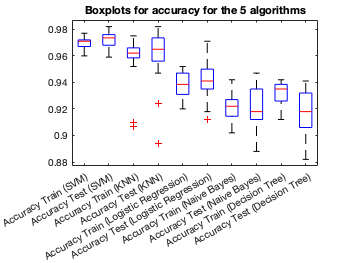

boxplot(x)
title("Boxplots for accuracy for the 5 algorithms")
xticklabels({'Accuracy Train (SVM)','Accuracy Test (SVM)','Accuracy Train (KNN)', 'Accuracy Test (KNN)','Accuracy Train (Logistic Regression)', 'Accuracy Test (Logistic Regression)','Accuracy Train (Naive Bayes)', 'Accuracy Test (Naive Bayes)','Accuracy Train (Decision Tree)','Accuracy Test (Decision Tree)'})


y = [speed.PredictionSpeedobssecSVM speed.PredictionSpeedobssecKNN speed.PredictionSpeedobssecLR speed.PredictionSpeedobssecNB speed.PredictionSpeedobssecDT]

y =        13000        5200        6500        1200       11000
        9900        6500        8900        1300        9600
       12000        6300       10000        1100       12000
        8900        5800        9400        1600        9000
        8100        2600        8600        1300       12000
       12000        3600        9200        1800       13000
       13000        5900        8800        1400       12000
       11000        5300        7800        1700       12000
       14000        6200        8500        1800        9800
       11000        6300        8800        1700       13000


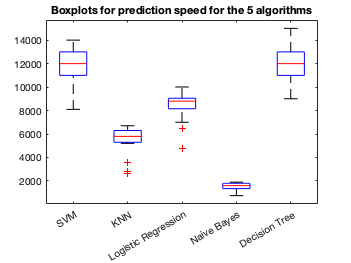

boxplot(y)
title("Boxplots for prediction speed for the 5 algorithms")
xticklabels({'SVM','KNN','Logistic Regression','Naive Bayes','Decision Tree'})


z = [time.TrainingTimesecSVM time.TrainingTimesecKNN time.TrainingTimesecLR time.TrainingTimesecNB time.TrainingTimesecDT]

z =     0.8806    0.9851    2.0033    4.2776    0.9743
    1.3640    0.9359    1.4648    3.7858    0.9257
    0.9302    1.0829    1.3983    3.8591    0.9894
    1.2818    1.0521    1.3460    3.6025    0.8747
    1.0836    1.6158    1.7093    3.5863    1.1775
    0.8354    1.4703    1.3855    2.9678    1.3086
    0.9822    1.0831    1.4149    3.8009    0.9307
    1.1689    1.0802    1.9038    4.0229    0.9429
    0.8738    0.9142    1.5777    2.9748    0.9788
    1.0197    0.9152    1.9108    3.3116    0.8480


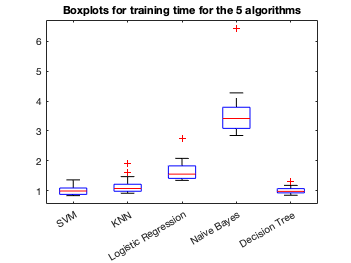

boxplot(z)
title("Boxplots for training time for the 5 algorithms")
xticklabels({'SVM','KNN','Logistic Regression','Naive Bayes','Decision Tree'})